# Første lektion - Frie udæmpede svingninger

- Vibration: Frie udæmpede svingninger

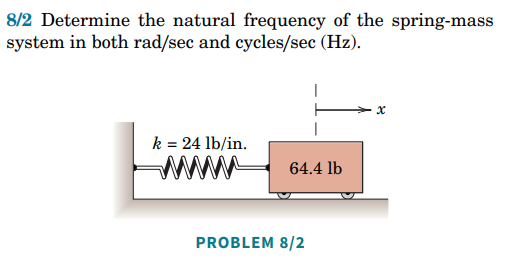

k = 4500 n/m

m = 20 kg

Bestem den naturlige frekvens i både rad/sec & Hz

clear

u = symunit;
k = 4500;
m = 20;

omega = sqrt(k/m) 
ln    = omega/(2*pi)


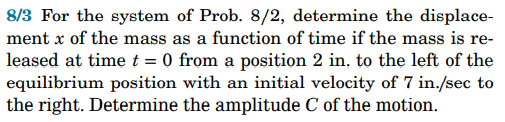

Informationer:


$$x(0) = -30 mm = x_0$$



$$\dot{x}(0) = 120 mm/s = v_0$$


Formlen, som vi skal anvende til at finde C, amplituden:


$$C = \sqrt{x_0^2 + (\dot{x_0}/\omega_n)^2}$$



$$\phi = arctan( (x_0*\omega_n)/\dot{x_0} )$$




x_0 = -30;
V_0 = 120;

C = vpa(sqrt(x_0^2 + (V_0/omega)^2))
Phi = vpa(atan((x_0 * omega)/V_0))

t = linspace(0,3,300);
x = @(t) C * sin(omega*t - Phi);

plot(t,x(t))

Så bliver afstanden som funktion af tid: 


$$x(t) = 31.048 * sin(15 \frac{Rad}{Sec}*(t) - 1.31*Rad)$$


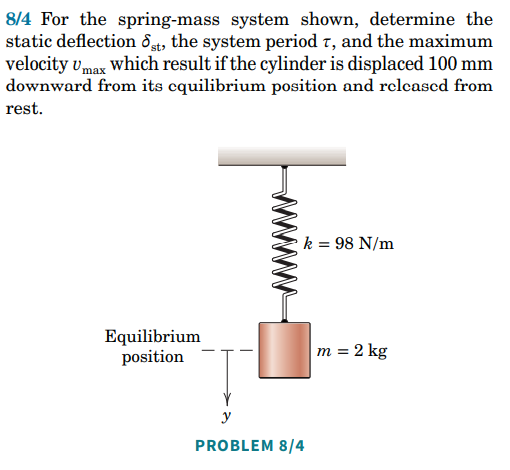

Informationer:


$$k = 98 N/m$$



$$m = 2 kg$$



$$x_0 = 100 mm$$


Formler:


$$C = \sqrt{A^2 + B^2} \rightarrow x_0 = A*cos(\omega_n * 0) + 0 \rightarrow A = x_0$$



$$C = 100$$



$$\sigma_{st} = \frac{Weight}{k} \rightarrow \frac{(m*g)}{k}$$



$$t = \frac{2*\pi}{\omega}$$



$$\omega_n = \sqrt(\frac{k}{m})$$


clear

k = 98;
m = 2;

g = 9.81;

x_0 = 100
V_0 = 0

omega = sqrt(k/m)

C = sqrt(x_0^2+(V_0/omega)^2)

psi = atan(x_0*omega/V_0)

Statisk_Deflektion = vpa(((m*g)/k),4)

tid_mellem_amplitude = (2*pi)/omega

syms x(t)

x(t) = C * sin(omega*t + psi)

dxdt(t) = diff(x(t),t)

fplot(dxdt) % Hastighedsgraf

tid_hvor_V_max = solve(x(t) == 0,t) % Tiden, hvor vi har den højeste hastighed

vpa(dxdt(tid_hvor_V_max),3) % Angiver Maksimale hastighed.


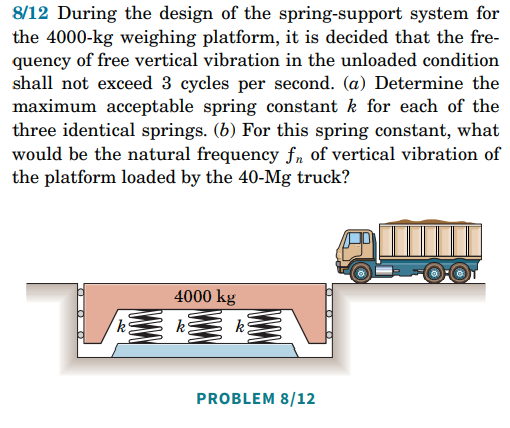

Informationer:

- Objekt:

- masse = 4000 kg

- Weight = 4000 kg * 9.81 m/s^2


$$k = 4000/3$$


clear

m = 4000;
Lastbil = 40000;
hz = 3;
omega = (2*pi)/hz;

syms k
k_minimum = vpa(solve(hz == (1/(2*pi))*sqrt((3*k)/m),k),6)

frekvens = vpa((sqrt((3*k_minimum)/(m+Lastbil)))/(2*pi),3)


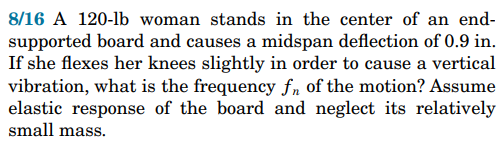

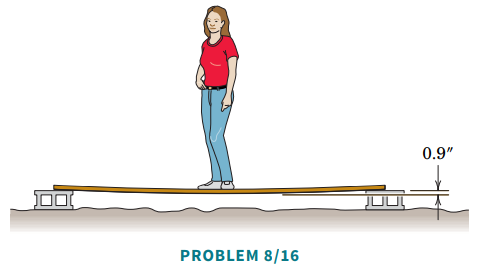

- Informationer

- Vægt: 120 Lbs = 55 kg

- Den statiske deflektion: 0.9 tommer = 2.286 cm -> 2.5 cm

Formler vi anvender:

- Den statiske deformation: $\sigma_{st} = \frac{m \cdot g}{k}$

- Omega: $\omega = \sqrt{\frac{k}{m}}$

- Frekvensen: $Hz = \frac{\omega}{2 \cdot \pi}$

clear
Mass = 55;
Deflation = 0.022;
Gravity = 9.81;

k = vpa((Mass * Gravity)/Deflation,6)
Omega = vpa(sqrt(k/Mass),6)
Hz = vpa(Omega/(2*pi),6)